We compute SSM compute for an Oscillator Chain with cubic and quadratic nonlinearities

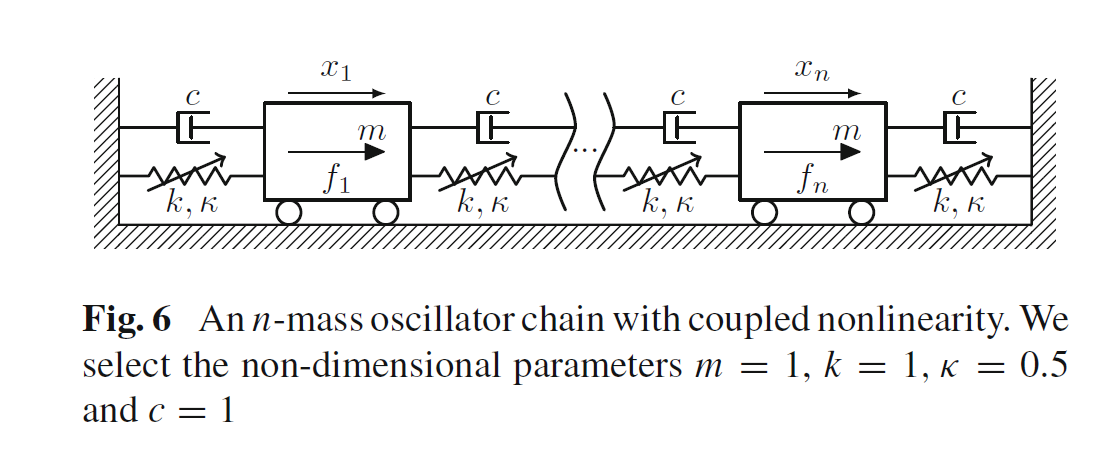

## Example setup

n = 100;
m = 1;
k = 1;
c = 0.1;
kappa2 = 0;
kappa3 = 0.5;

[M,C,K,fnl,~] = build_model(n,m,c,k,kappa2,kappa3);

## Dynamical system setup 

We consider the forced system


$$\mathbf{M}\ddot{\mathbf{x}}+\mathbf{C}\dot{\mathbf{x}}+\mathbf{K}\mathbf{x}+\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})=\epsilon\mathbf{f}^{ext}(\mathbf{\Omega}t),$$


which can be written in the first-order form as 


$$\mathbf{B}\dot{\mathbf{z}}	=\mathbf{Az}+\mathbf{F}(\mathbf{z})+\epsilon\mathbf{F}^{ext}(\mathbf{\phi}),\\\dot{\mathbf{\phi}}	
=\mathbf{\Omega}$$


where

$\mathbf{z}=\left[\begin{array}{c}\mathbf{x}\\\dot{\mathbf{x}}\end{array}\right],\quad\mathbf{A}=\left[\begin{array}{cc}-\mathbf{K} 
& \mathbf{0}\\\mathbf{0} & \mathbf{M}\end{array}\right],\mathbf{B}=\left[\begin{array}{cc}\mathbf{C} 
& \mathbf{M}\\\mathbf{M} & \mathbf{0}\end{array}\right],\quad\quad\mathbf{F}(\mathbf{z})=\left[\begin{array}{c}\mathbf{-\mathbf{f}(\mathbf{x},\dot{\mathbf{x}})}\\\mathbf{0}\end{array}\right],\quad\mathbf{F}^{ext}(\mathbf{z},\mathbf{\phi})=\left[\begin{array}{c}
\mathbf{f}^{ext}(\mathbf{\phi})\\
\mathbf{0}
\end{array}\right]$.

DS = DynamicalSystem();
set(DS,'M',M,'C',C,'K',K,'fnl',fnl);
set(DS.Options,'Emax',30,'Nmax',30,'notation','multiindex')
% set(DS.Options,'Emax',5,'Nmax',100,'notation','tensor')

We assume periodic forcing of the form


$$\mathbf{f}^{ext}(\phi) = \mathbf{f}_0\cos(\phi)=\frac{\mathbf{f}_0}{2}e^{i\phi} + \frac{\mathbf{f}_0}{2}e^{-i\phi}  $$


epsilon = 5e-3;
f_0 = ones(n,1);

Fourier coefficients of Forcing

kappas = [-1; 1];
coeffs = [f_0 f_0]/2;
DS.add_forcing(coeffs, kappas,epsilon);

## Linear Modal analysis and SSM setup

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 30 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 1.555181e-03
modal damping ratio for 2 mode is 3.109986e-03
modal damping ratio for 3 mode is 4.664039e-03
modal damping ratio for 4 mode is 6.216964e-03
modal damping ratio for 5 mode is 7.768385e-03
modal damping ratio for 6 mode is 9.317927e-03
modal damping ratio for 7 mode is 1.086522e-02
modal damping ratio for 8 mode is 1.240988e-02
modal damping ratio for 9 mode is 1.395153e-02
modal damping ratio for 10 mode is 1.548982e-02
modal damping ratio for 11 mode is 1.702436e-02
modal damping ratio for 12 mode is 1.855478e-02
modal damping ratio for 13 mode is 2.008071e-02
modal damping ratio for 14 mode is 2.160178e-02
modal damping ratio for 15 mode is 2.311763e-02
modal damping ratio for 16 mode is 2.462789e-02
modal damping rati

plot_eigenvalues_in_complex_plane(D)

**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 0.1,'notation','multiindex')
% set(S.Options, 'reltol', 0.1,'notation','tensor')
masterModes = [1,2]; 
S.choose_E(masterModes);

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     3     1
     4     2
     5     3
     6     4
     0     2
     1     3
     2     4
     3     5
     4     6
     3     0
     4     1
     5     2
     6     3
     0     3
     1     4
     2     5
     3     6
     4     0
     5     1
     6     2
     7     3
     0     4
     1     5
     2     6
     3     7
     5     0
     6     1
     7     2
     0     5
     1     6
     2     7
     6     0
     7     1
     8     2
     0     6
     1     7
     2     8
     7     0
     8     1
     0     7
     1     8
     8     0
     9     1
     0     8
     1     9

These are in resonance with the follwing eigenvalues of the slave subspace
  -0.0002 + 0.0622i
  -0.0002 + 0.0622i
  -0.0002 + 0.0622i
  -0.0002 + 0.0622i
  -0.0002 + 0.0622i
  -0.0002 - 0.0622i
  -0.0002 - 0.0622i
  -0.0002 - 0.0622i
  -0.0002 - 0.0622i
  -0.0002 - 0.0622i
  -0.0004 + 0.0933i
  -0.0004 + 0.0933i
  

## Forced response curves using SSMs

Obtaining **forced response curve** in reduced-polar coordinate

order = 5; % Approximation order
outdof = floor(n/2);


setup options

set(S.Options, 'reltol', 1,'IRtol',0.02,'notation', 'multiindex','contribNonAuto',true)
set(S.FRCOptions, 'nt', 2^7, 'nRho', 200, 'nPar', 100, 'nPsi', 100, 'rhoScale', 2 )
set(S.FRCOptions, 'method','continuation ep') % 'level set' 
set(S.FRCOptions, 'outdof',outdof)

choose frequency range

omega0 = imag(S.E.spectrum(1));
omegaRange = omega0*[0.8 1.2];


extract backbone

(near) outer resonance detected for the following combination of master eigenvalues
     2     0
     2     1
     3     1
     3     2
     4     2
     4     3
     5     3
     5     4
     6     4
     0     2
     1     2
     1     3
     2     3
     2     4
     3     4
     3     5
     4     5
     4     6
     2     0
     3     0
     3     1
     4     1
     4     2
     5     2
     5     3
     6     3
     6     4
     0     2
     0     3
     1     3
     1     4
     2     4
     2     5
     3     5
     3     6
     4     6
     3     0
     4     0
     4     1
     5     1
     5     2
     6     2
     6     3
     7     3
     0     3
     0     4
     1     4
     1     5
     2     5
     2     6
     3     6
     3     7
     4     0
     5     0
     5     1
     6     1
     6     2
     7     2
     7     3
     0     4
     0     5
     1     5
     1     6
     2     6
     2     7
     3     7
     5     0
     6     0
     6     1
     7     1
     7

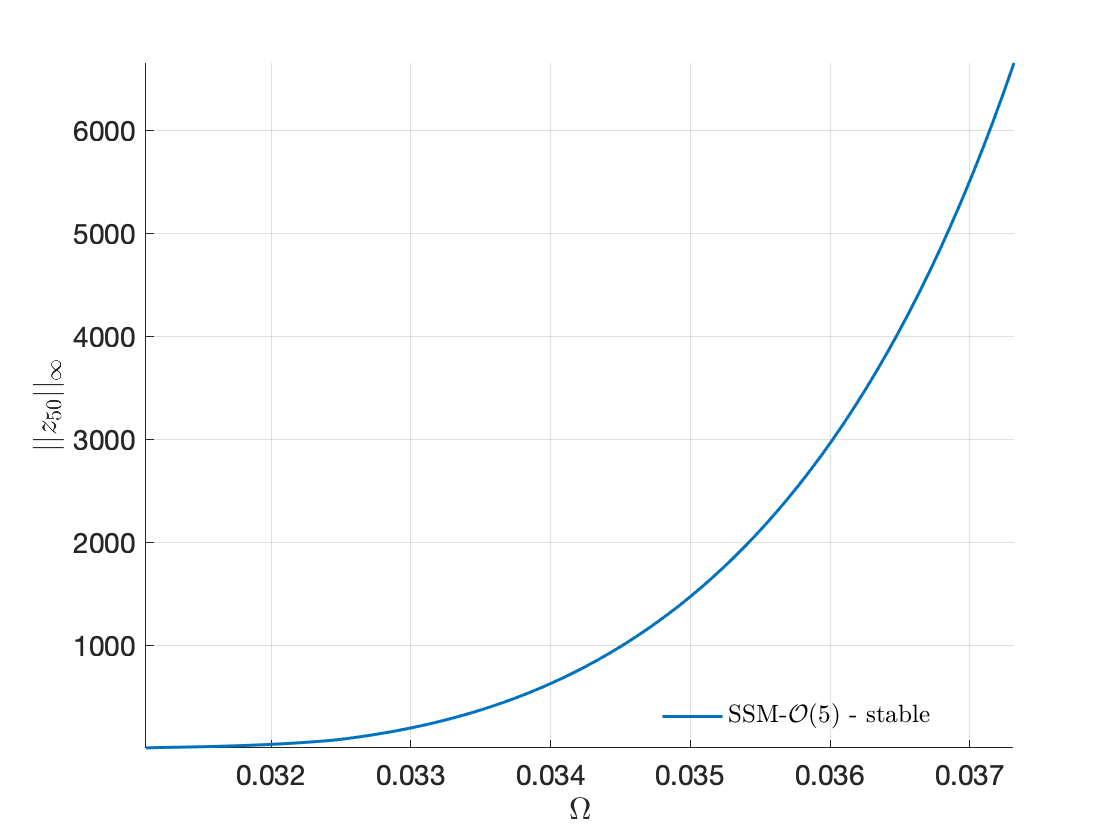

Total time spent on backbone curve computation = 00:00:01


BB = S.extract_backbone(masterModes,omegaRange, order);

figBB = gcf;

extract forced response curve

FRC = S.extract_FRC('freq',omegaRange,order);

The master subspace has internal resonances: [1  1  2  2  3  3  4  4  5  5]
*****************************************
Calculating FRC using SSM with master subspace: [1   2   3   4   5   6   7   8   9  10]
(near) outer resonance detected for the following combination of master eigenvalues
     0     0     0     0     2     0     0     0     0     0
     0     0     1     0     0     0     1     0     0     0
     0     0     1     0     1     0     0     0     0     0
     1     0     0     0     0     0     0     0     1     0
     1     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     2     1
     0     0     0     0     0     0     0     1     2     0
     0     0     0     0     0     0     1     1     1     0
     0     0     0     0     0     1     1     0     1     0
     0     0     0     0     0     1     2     0     0     0
     0     0     0     0     1     1     0     0     1     0
     0     0     0     1     0     0   

Error using SSM/FRC_cont_ep>extract_beta_kappa (line 295)
Reduced dynamics is not consisent with desired IRs

Error in SSM/FRC_cont_ep (line 49)
[beta,kappa] = extract_beta_kappa(m,order,R_0,mFreqs);

Error in 

figFRC = gcf;